# EMG and Movement

The following will calculate the RMS for EMG data coming from two muscles during arm movement in two planes. 

Also, it calculates ROM for kinematic data for scapular tilt and scapular upward rotation in two planes.

% lets clear everything
clc; clear;

%Also, we want to show the long(short) version of decimal data
format short g

### Load data

We have data from 22 subjects. 

Note that from subject 2, Trials variable doesnt exist, TrialsPre and TrialsPost should be used instead. 

Also, subjects 7 and 8 lack of PreFrontal EMG data ( both excluded from analysis)

target = "S03" % here modify target subject

target = "S03"

currentFolder = pwd

currentFolder = 'C:\Users\Usuario\Documents\GitHub\ViconMatlab\KT'

destination = [pwd,"\DataMatlab\",target,".mat"];
targetData = join(destination,"");
load(targetData); %this folder may vary

### Setting up variables

We need to store data from each time window into cells. 

Ideally we use arrays to store data, but our data is uneven due time window (frames) 

frontalMovPre50 = {};
frontalMovPost50 = {};
frontalMovPre100 = {};
frontalMovPost100 = {};

sagitalMovPre50 = {};
sagitalMovPost50 = {};
sagitalMovPre100 = {};
sagitalMovPost100 = {};

frontalMusclePre50 = {};
frontalMusclePost50 = {};
frontalMusclePre100 = {};
frontalMusclePost100 = {};

sagitalMusclePre50 = {};
sagitalMusclePost50 = {};
sagitalMusclePre100 = {};
sagitalMusclePost100 = {};

### Filtering Stage

Set up a low pass filter

Fs = 100; %  Sample freq
Fc = [10 0.4 10]; %  Cut freq
% Frequencies were calculated from Fourier Analysis
FTilt = Fc(1)/(Fs/2); %  Cutoff frequency for Tilt Mov
FUpward = Fc(2)/(Fs/2); %  Cutoff frequency for Upward Rotation Mov
FAbd = Fc(3)/(Fs/2); %  Cutoff frequency for Abduction Mov

%Scapular Tilt Movement
df = designfilt('lowpassfir','FilterOrder',100,'CutoffFrequency',FTilt); %  design filter
Frontal_Pre_ScapularTilt = filtfilt(df,Frontal_Pre_ScapularTilt);
Frontal_Post_ScapularTilt = filtfilt(df,Frontal_Post_ScapularTilt);

%Scapular Upward Movement
df = designfilt('lowpassfir','FilterOrder',100,'CutoffFrequency',FUpward); %  design filter
Frontal_Pre_ScapularUpward = filtfilt(df,Frontal_Pre_ScapularUpward);
Frontal_Post_ScapularUpward = filtfilt(df,Frontal_Post_ScapularUpward);

%Humerus Movement - Frontal Plane  
df = designfilt('lowpassfir','FilterOrder',100,'CutoffFrequency',FAbd); %  design filter
Frontal_Pre_HumeroFrontal = filtfilt(df,Frontal_Pre_HumeroFrontal);
Frontal_Post_HumeroFrontal = filtfilt(df,Frontal_Post_HumeroFrontal);

%Humerus Movement - Sagital Plane
df = designfilt('lowpassfir','FilterOrder',100,'CutoffFrequency',FAbd); %  design filter
Escapular_Pre_HumeroScapular = filtfilt(df,Escapular_Pre_HumeroScapular);
Escapular_Post_HumeroScapular = filtfilt(df,Escapular_Post_HumeroScapular);


### Read and Store data

We need to store our data divided by two conditions, Target 50 and Target 100. 

Also, data must be sectioned into each plane, Frontal, Sagital. 

This section will assign each segment of data from Movement and EMG into the previously defined cells. 

if target == "S02"
    for i=1:10
        if TrialsPre(i) == 50 % Pre-intervention (target 50°)
            % Kinematics
            data1Pre50 = Frontal_Pre_ScapularTilt(framesPreFrontal(i,1):framesPreFrontal(i,2));
            data2Pre50 = Frontal_Pre_ScapularUpward(framesPreFrontal(i,1):framesPreFrontal(i,2));
            data3Pre50 = Frontal_Pre_HumeroFrontal(framesPreFrontal(i,1):framesPreFrontal(i,2));
            data4Pre50 = Escapular_Pre_HumeroScapular(framesPreEscapular(i,1):framesPreEscapular(i,2));
            
            % EMG
            frontal_serratoPre50_ROI = SerratoPreFrontal(framesPreFrontal(i,1)*20:framesPreFrontal(i,2)*20);
            frontal_trapezioPre50_ROI = TrapezioPreFrontal(framesPreFrontal(i,1)*20:framesPreFrontal(i,2)*20);
            sagital_serratoPre50_ROI = SerratoPreEscapular(framesPreEscapular(i,1)*20:framesPreEscapular(i,2)*20);
            sagital_trapezioPre50_ROI = TrapezioPreEscapular(framesPreEscapular(i,1)*20:framesPreEscapular(i,2)*20);
            
            % Join data 
            sagitalMusclePre50 = [sagitalMusclePre50, sagital_serratoPre50_ROI, sagital_trapezioPre50_ROI]; % Serrato - Trapezio Pre 50 (Sagital plane)
            frontalMusclePre50 = [frontalMusclePre50, frontal_serratoPre50_ROI, frontal_trapezioPre50_ROI]; % Serrato - Trapezio Pre 50 (Frontal plane)

            frontalMovPre50 = [frontalMovPre50, data1Pre50, data2Pre50, data3Pre50]; % ScapTilt - ScapUp - HumeroAbd Pre 50 (Frontal plane)
            sagitalMovPre50 = [sagitalMovPre50, data4Pre50]; % HumeroAbd Pre 50 (Sagital plane)
        end
        if TrialsPost(i) == 50% Post-intervention
            %Kinematics
            data1Post50 = Frontal_Post_ScapularTilt(framesPostFrontal(i,1):framesPostFrontal(i,2));
            data2Post50 = Frontal_Post_ScapularUpward(framesPostFrontal(i,1):framesPostFrontal(i,2));
            data3Post50 = Frontal_Post_HumeroFrontal(framesPostFrontal(i,1):framesPostFrontal(i,2));
            data4Post50 = Escapular_Post_HumeroScapular(framesPostEscapular(i,1):framesPostEscapular(i,2));
            
            % EMG
            frontal_serratoPost50_ROI = SerratoPostFrontal(framesPostFrontal(i,1)*20:framesPostFrontal(i,2)*20);
            frontal_trapezioPost50_ROI = TrapezioPostFrontal(framesPostFrontal(i,1)*20:framesPostFrontal(i,2)*20);
            sagital_serratoPost50_ROI = SerratoPostEscapular(framesPostEscapular(i,1)*20:framesPostEscapular(i,2)*20);
            sagital_trapezioPost50_ROI = TrapezioPostEscapular(framesPostEscapular(i,1)*20:framesPostEscapular(i,2)*20);
            
            % Join data 
            sagitalMusclePost50 = [sagitalMusclePost50, sagital_serratoPost50_ROI, sagital_trapezioPost50_ROI]; % Serrato - Trapezio Post 50 (Sagital plane)
            frontalMusclePost50 = [frontalMusclePost50, frontal_serratoPost50_ROI, frontal_trapezioPost50_ROI]; % Serrato - Trapezio Post 50 (Frontal plane)

            frontalMovPost50 = [frontalMovPost50, data1Post50, data2Post50, data3Post50]; % ScapTilt - ScapUp - HumeroAbd Post 50 (Frontal plane)
            sagitalMovPost50 = [sagitalMovPost50, data4Post50]; % HumeroAbd Post 50 (Sagital plane)
        end
        if TrialsPre(i) == 100 % Pre-intervention (target 100°)
            % Kinematics
            data1Pre100 = Frontal_Pre_ScapularTilt(framesPreFrontal(i,1):framesPreFrontal(i,2));
            data2Pre100 = Frontal_Pre_ScapularUpward(framesPreFrontal(i,1):framesPreFrontal(i,2));
            data3Pre100 = Frontal_Pre_HumeroFrontal(framesPreFrontal(i,1):framesPreFrontal(i,2));
            data4Pre100 = Escapular_Pre_HumeroScapular(framesPreEscapular(i,1):framesPreEscapular(i,2));
            
            % EMG
            frontal_serratoPre100_ROI = SerratoPreFrontal(framesPreFrontal(i,1)*20:framesPreFrontal(i,2)*20);
            frontal_trapezioPre100_ROI = TrapezioPreFrontal(framesPreFrontal(i,1)*20:framesPreFrontal(i,2)*20);
            sagital_serratoPre100_ROI = SerratoPreEscapular(framesPreEscapular(i,1)*20:framesPreEscapular(i,2)*20);
            sagital_trapezioPre100_ROI = TrapezioPreEscapular(framesPreEscapular(i,1)*20:framesPreEscapular(i,2)*20);

            sagitalMusclePre100 = [sagitalMusclePre100, sagital_serratoPre100_ROI, sagital_trapezioPre100_ROI]; % Serrato - Trapezio Pre 100 (Sagital plane)
            frontalMusclePre100 = [frontalMusclePre100, frontal_serratoPre100_ROI, frontal_trapezioPre100_ROI]; % Serrato - Trapezio Pre 100 (Frontal plane)

            frontalMovPre100 = [frontalMovPre100, data1Pre100, data2Pre100, data3Pre100]; % ScapTilt - ScapUp - HumeroAbd Pre 100 (Frontal plane)
            sagitalMovPre100 = [sagitalMovPre100, data4Pre100]; % HumeroAbd Pre 100 (Sagital plane)
        end
        if TrialsPost(i) == 100 % Post-intervention (target 100°)
            % Kinematics
            data1Post100 = Frontal_Post_ScapularTilt(framesPostFrontal(i,1):framesPostFrontal(i,2));
            data2Post100 = Frontal_Post_ScapularUpward(framesPostFrontal(i,1):framesPostFrontal(i,2));
            data3Post100 = Frontal_Post_HumeroFrontal(framesPostFrontal(i,1):framesPostFrontal(i,2));
            data4Post100 = Escapular_Post_HumeroScapular(framesPostEscapular(i,1):framesPostEscapular(i,2));
            
            % EMG
            frontal_serratoPost100_ROI = SerratoPostFrontal(framesPostFrontal(i,1)*20:framesPostFrontal(i,2)*20);
            frontal_trapezioPost100_ROI = TrapezioPostFrontal(framesPostFrontal(i,1)*20:framesPostFrontal(i,2)*20);
            sagital_serratoPost100_ROI = SerratoPostEscapular(framesPostEscapular(i,1)*20:framesPostEscapular(i,2)*20);
            sagital_trapezioPost100_ROI = TrapezioPostEscapular(framesPostEscapular(i,1)*20:framesPostEscapular(i,2)*20);

            sagitalMusclePost100 = [sagitalMusclePost100, sagital_serratoPost100_ROI, sagital_trapezioPost100_ROI]; % Serrato - Trapezio Pre 100 (Sagital plane)
            frontalMusclePost100 = [frontalMusclePost100, frontal_serratoPost100_ROI, frontal_trapezioPost100_ROI]; % Serrato - Trapezio Post 100 (Frontal plane)

            frontalMovPost100 = [frontalMovPost100, data1Post100, data2Post100, data3Post100]; % ScapTilt - ScapUp - HumeroAbd Post 100 (Frontal plane)
            sagitalMovPost100 = [sagitalMovPost100, data4Post100]; % HumeroAbd Post 100 (Sagital plane)
        end
    end
% subjects besides S02
else
    for i=1:10
        if Trials(i) == 50  %if i in trials is 50 (target), take frames from each plane, pre-post, and store Region of Interest
            % for EMG, multiply for 20 to match the difference in sample
            % frequency of kinematics (100 hz) and EMG (2000 hz)
            data1Pre50 = Frontal_Pre_ScapularTilt(framesPreFrontal(i,1):framesPreFrontal(i,2));
            data1Post50 = Frontal_Post_ScapularTilt(framesPostFrontal(i,1):framesPostFrontal(i,2));
            data2Pre50 = Frontal_Pre_ScapularUpward(framesPreFrontal(i,1):framesPreFrontal(i,2));
            data2Post50 = Frontal_Post_ScapularUpward(framesPostFrontal(i,1):framesPostFrontal(i,2));
            data3Pre50 = Frontal_Pre_HumeroFrontal(framesPreFrontal(i,1):framesPreFrontal(i,2));
            data3Post50 = Frontal_Post_HumeroFrontal(framesPostFrontal(i,1):framesPostFrontal(i,2));
            data4Pre50 = Escapular_Pre_HumeroScapular(framesPreEscapular(i,1):framesPreEscapular(i,2));
            data4Post50 = Escapular_Post_HumeroScapular(framesPostEscapular(i,1):framesPostEscapular(i,2));

            frontal_serratoPre50_ROI = SerratoPreFrontal(framesPreFrontal(i,1)*20:framesPreFrontal(i,2)*20);
            frontal_serratoPost50_ROI = SerratoPostFrontal(framesPostFrontal(i,1)*20:framesPostFrontal(i,2)*20);
            frontal_trapezioPre50_ROI = TrapezioPreFrontal(framesPreFrontal(i,1)*20:framesPreFrontal(i,2)*20);
            frontal_trapezioPost50_ROI = TrapezioPostFrontal(framesPostFrontal(i,1)*20:framesPostFrontal(i,2)*20);

            sagital_serratoPre50_ROI = SerratoPreEscapular(framesPreEscapular(i,1)*20:framesPreEscapular(i,2)*20);
            sagital_serratoPost50_ROI = SerratoPostEscapular(framesPostEscapular(i,1)*20:framesPostEscapular(i,2)*20);
            sagital_trapezioPre50_ROI = TrapezioPreEscapular(framesPreEscapular(i,1)*20:framesPreEscapular(i,2)*20);
            sagital_trapezioPost50_ROI = TrapezioPostEscapular(framesPostEscapular(i,1)*20:framesPostEscapular(i,2)*20);

            sagitalMusclePre50 = [sagitalMusclePre50, sagital_serratoPre50_ROI, sagital_trapezioPre50_ROI]; % Serrato - Trapezio Pre 50 (Sagital plane)
            sagitalMusclePost50 = [sagitalMusclePost50, sagital_serratoPost50_ROI, sagital_trapezioPost50_ROI]; % Serrato - Trapezio Post 50 (Sagital plane)

            frontalMusclePre50 = [frontalMusclePre50, frontal_serratoPre50_ROI, frontal_trapezioPre50_ROI]; % Serrato - Trapezio Pre 50 (Frontal plane)
            frontalMusclePost50 = [frontalMusclePost50, frontal_serratoPost50_ROI, frontal_trapezioPost50_ROI]; % Serrato - Trapezio Post 50 (Frontal plane)

            frontalMovPre50 = [frontalMovPre50, data1Pre50, data2Pre50, data3Pre50]; % ScapTilt - ScapUp - HumeroAbd Pre 50 (Frontal plane)
            frontalMovPost50 = [frontalMovPost50, data1Post50, data2Post50, data3Post50]; % ScapTilt - ScapUp - HumeroAbd Post 50 (Frontal plane)

            sagitalMovPre50 = [sagitalMovPre50, data4Pre50]; % HumeroAbd Pre 50 (Sagital plane)
            sagitalMovPost50 = [sagitalMovPost50, data4Post50]; % HumeroAbd Post 50 (Sagital plane)

        elseif Trials(i) == 100
            data1Pre100 = Frontal_Pre_ScapularTilt(framesPreFrontal(i,1):framesPreFrontal(i,2));
            data1Post100 = Frontal_Post_ScapularTilt(framesPostFrontal(i,1):framesPostFrontal(i,2));
            data2Pre100 = Frontal_Pre_ScapularUpward(framesPreFrontal(i,1):framesPreFrontal(i,2));
            data2Post100 = Frontal_Post_ScapularUpward(framesPostFrontal(i,1):framesPostFrontal(i,2));
            data3Pre100 = Frontal_Pre_HumeroFrontal(framesPreFrontal(i,1):framesPreFrontal(i,2));
            data3Post100 = Frontal_Post_HumeroFrontal(framesPostFrontal(i,1):framesPostFrontal(i,2));
            data4Pre100 = Escapular_Pre_HumeroScapular(framesPreEscapular(i,1):framesPreEscapular(i,2));
            data4Post100 = Escapular_Post_HumeroScapular(framesPostEscapular(i,1):framesPostEscapular(i,2));

            frontal_serratoPre100_ROI = SerratoPreFrontal(framesPreFrontal(i,1)*20:framesPreFrontal(i,2)*20);
            frontal_serratoPost100_ROI = SerratoPostFrontal(framesPostFrontal(i,1)*20:framesPostFrontal(i,2)*20);
            frontal_trapezioPre100_ROI = TrapezioPreFrontal(framesPreFrontal(i,1)*20:framesPreFrontal(i,2)*20);
            frontal_trapezioPost100_ROI = TrapezioPostFrontal(framesPostFrontal(i,1)*20:framesPostFrontal(i,2)*20);

            sagital_serratoPre100_ROI = SerratoPreEscapular(framesPreEscapular(i,1)*20:framesPreEscapular(i,2)*20);
            sagital_serratoPost100_ROI = SerratoPostEscapular(framesPostEscapular(i,1)*20:framesPostEscapular(i,2)*20);
            sagital_trapezioPre100_ROI = TrapezioPreEscapular(framesPreEscapular(i,1)*20:framesPreEscapular(i,2)*20);
            sagital_trapezioPost100_ROI = TrapezioPostEscapular(framesPostEscapular(i,1)*20:framesPostEscapular(i,2)*20);

            sagitalMusclePre100 = [sagitalMusclePre100, sagital_serratoPre100_ROI, sagital_trapezioPre100_ROI]; % Serrato - Trapezio Pre 100 (Sagital plane)
            sagitalMusclePost100 = [sagitalMusclePost100, sagital_serratoPost100_ROI, sagital_trapezioPost100_ROI]; % Serrato - Trapezio Pre 100 (Sagital plane)

            frontalMusclePre100 = [frontalMusclePre100, frontal_serratoPre100_ROI, frontal_trapezioPre100_ROI]; % Serrato - Trapezio Pre 100 (Frontal plane)
            frontalMusclePost100 = [frontalMusclePost100, frontal_serratoPost100_ROI, frontal_trapezioPost100_ROI]; % Serrato - Trapezio Post 100 (Frontal plane)

            frontalMovPre100 = [frontalMovPre100, data1Pre100, data2Pre100, data3Pre100]; % ScapTilt - ScapUp - HumeroAbd Pre 100 (Frontal plane)
            frontalMovPost100 = [frontalMovPost100, data1Post100, data2Post100, data3Post100]; % ScapTilt - ScapUp - HumeroAbd Post 100 (Frontal plane)

            sagitalMovPre100 = [sagitalMovPre100, data4Pre100]; % HumeroAbd Pre 100 (Sagital plane)
            sagitalMovPost100 = [sagitalMovPost100, data4Post100]; % HumeroAbd Post 100 (Sagital plane)
        end
    end
end

## Functions

There are four functions designed to calculate biomechanic aspects from our data. 

ROM Calculation and RMS Calculation, one for each plane. 

detailed explanation of each formula it is written in its respective section

showPlot = false; % for debug

#### Frontal Plane - ROM Calculation

[scapTiltRomPre50, scapTiltRomPost50, scapTiltRomPre100, scapTiltRomPost100, scapUpRomPre50, scapUpRomPost50,scapUpRomPre100, scapUpRomPost100, abdRomPre50, abdRomPost50, abdRomPre100, abdRomPost100] = frontalRomCalculation(frontalMovPre50, frontalMovPost50, frontalMovPre100, frontalMovPost100, showPlot);

#### Sagital Plane - ROM Calculation

% [sagitalbAbdRomPre50, sagitalbAbdRomPost50, sagitalbAbdRomPre100, sagitalbAbdRomPost100] = sagitalRomCalculation(sagitalMovPre50, sagitalMovPost50, sagitalMovPre100, sagitalMovPost100, showPlot);

#### Frontal Plane - RMS Calculation

[serratoPre50, serratoPre100, serratoPost50, serratoPost100, trapezioPre50, trapezioPre100, trapezioPost50, trapezioPost100] = frontal_rmsCalculation(frontalMusclePre50, frontalMusclePost50, frontalMusclePre100, frontalMusclePost100);

#### Sagital Plane - RMS Calculation

% [sagitalSerratoPre50, sagitalSerratoPre100, sagitalSerratoPost50, sagitalSerratoPost100, sagitalTrapezioPre50, sagitalTrapezioPre100, sagitalTrapezioPost50, sagitalTrapezioPost100] = sagital_rmsCalculation(sagitalMusclePre50, sagitalMusclePost50, sagitalMusclePre100, sagitalMusclePost100);

### Save Data

Once each desired calculation has been made, data will be save into a .csv file

Data is organized as following: 

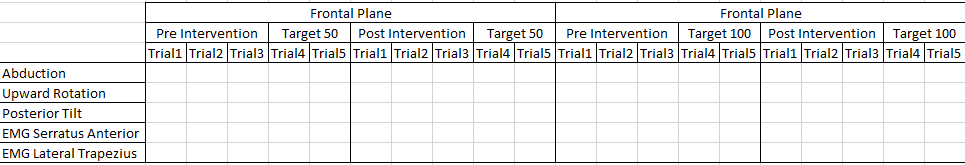

    and then the next plane. 

%{
zero = zeros(1,5); % create zeros in order to fill the empty spaces
varNames = {'Pre50';'Post50';'Pre100';'Post100';'SPre50';'SPost50';'SPre100';'SPost100' };
F = table([abdRomPre50; scapUpRomPre50; scapTiltRomPre50;serratoPre50;trapezioPre50], ...
    [abdRomPost50; scapUpRomPost50; scapTiltRomPost50;serratoPost50;trapezioPost50], ...
    [abdRomPre100; scapUpRomPre100; scapTiltRomPre100;serratoPre100;trapezioPre100], ...
    [abdRomPost100; scapUpRomPost100; scapTiltRomPost100;serratoPost100;trapezioPost100], ...
    [sagitalbAbdRomPre50; zero; zero ;sagitalSerratoPre50; sagitalTrapezioPre50], ...
    [sagitalbAbdRomPost50; zero ; zero ;sagitalSerratoPost50; sagitalTrapezioPost50], ...
    [sagitalbAbdRomPre100; zero ; zero ;sagitalSerratoPre100; sagitalTrapezioPre100],...
    [sagitalbAbdRomPost100; zero ; zero ;sagitalSerratoPost100; sagitalTrapezioPost100],...
    'VariableNames',varNames);


writetable(F,'data.csv');
%}
disp('Done')

Done


## Functions

#### ROM Calculation

This function will take data from one plane for both Pre and Post states and both target angles. 

It will determine the moment (frame) when the movement is starting and when is ending, and by simple subtraction will calculate the total movement performed by the arm. 

#### Frontal Plane

function [scapTiltRomPre50, scapTiltRomPost50, scapTiltRomPre100, scapTiltRomPost100, scapUpRomPre50, scapUpRomPost50,scapUpRomPre100, scapUpRomPost100, abdRomPre50, abdRomPost50, abdRomPre100, abdRomPost100 ] = frontalRomCalculation(frontalMovPre50, frontalMovPost50, frontalMovPre100, frontalMovPost100, showPlot)

temp1 = [];
temp2 = [];
temp3 = [];
temp4 = [];

temp5 = [];
temp6 = [];
temp7 = [];
temp8 = [];

temp9 = [];
temp10 = [];
temp11 = [];
temp12 = [];

for i = 1:3:15

    A = frontalMovPre50{:,i};
    B = frontalMovPre100{:,i};
    C = frontalMovPost50{:,i};
    D = frontalMovPost100{:,i};

    %     A = abs(A);
    %     B = abs(B);
    %     C = abs(C);
    %     D = abs(D);

    [endMovPre50, endIndex50] = max(A);
    [startMovPre50, index1] = min(A(1:endIndex50));
    temp1 = [temp1, endMovPre50-startMovPre50]; %ScapTilt Pre50

    [endMovPre100, endIndex100] = max(B);
    [startMovPre100, index2] = min(B(1:endIndex100));
    temp2 = [temp2, endMovPre100-startMovPre100]; %ScapTilt Pre100

    %Scapular Tilt Plot
    if showPlot == true
        subplot(4,3,1)
        plot(A)
        hold on
        plot(endIndex50, endMovPre50, 'rx')
        plot(index1, startMovPre50, 'bo')
        title('ScapularTilt Pre - 50')

        subplot(4,3,4)
        plot(B)
        hold on
        plot(endIndex100, endMovPre100, 'rx')
        plot(index2, startMovPre100, 'bo')
        title('ScapularTilt Pre - 100')
    end

    [endMovPost50, endIndex50] = max(C);
    [startMovPost50, index3] = min(C(1:endIndex50));
    temp3 = [temp3, endMovPost50-startMovPost50]; %ScapTilt Post50

    [endMovPost100, endIndex100] = max(D);
    [startMovPost100, index4] = min(D(1:endIndex100));
    temp4 = [temp4, endMovPost100-startMovPost100]; %ScapTilt Post100
    
    if showPlot == true
        subplot(4,3,7)
        plot(C)
        hold on
        plot(endIndex50, endMovPost50, 'rx')
        plot(index3, startMovPost50, 'bo')
        title('ScapularTilt Post - 50')

        subplot(4,3,10)
        plot(D)
        hold on
        plot(endIndex100, endMovPost100, 'rx')
        plot(index4, startMovPost100, 'bo')
        title('ScapularTilt Post - 100')
    end
end

for i = 2:3:15 % movement 2

    A = frontalMovPre50{:,i};
    B = frontalMovPre100{:,i};
    C = frontalMovPost50{:,i};
    D = frontalMovPost100{:,i};

    [endMovPre50, endIndex50] = max(A);
    [startMovPre50, index1] = min(A(1:endIndex50));
    temp5 = [temp5, endMovPre50-startMovPre50]; %ScapUp Pre50

    [endMovPre100, endIndex100] = max(B);
    [startMovPre100, index2] = min(B(1:endIndex100));
    temp6 = [temp6, endMovPre100-startMovPre100]; %ScapUp Pre100

    %Scapular Upward Rotation
    if showPlot == true
        subplot(4,3,2)
        plot(A)
        hold on
        plot(endIndex50, endMovPre50, 'rx')
        plot(index1, startMovPre50, 'bo')
        title('ScapularUpward Pre - 50')

        subplot(4,3,5)
        plot(B)
        hold on
        plot(endIndex100, endMovPre100, 'rx')
        plot(index2, startMovPre100, 'bo')
        title('ScapularUpward Pre - 100')
    end

    [endMovPost50, endIndex50] = max(C);
    [startMovPost50, index3] = min(C(1:endIndex50));
    temp7 = [temp7, endMovPost50-startMovPost50]; %ScapUp Post50

    [endMovPost100, endIndex100] = max(D);
    [startMovPost100, index4] = min(D(1:endIndex100));
    temp8 = [temp8, endMovPost100-startMovPost100]; %ScapUp Post100

    if showPlot == true
        subplot(4,3,8)
        plot(C)
        hold on
        plot(endIndex50, endMovPost50, 'rx')
        plot(index3, startMovPost50, 'bo')
        title('ScapularUpward Post - 50')

        subplot(4,3,11)
        plot(D)
        hold on
        plot(endIndex100, endMovPost100, 'rx')
        plot(index4, startMovPost100, 'bo')
        title('ScapularUpward Post - 100')
    end
end

for i = 3:3:15 % movement 3
    A = frontalMovPre50{:,i};
    B = frontalMovPre100{:,i};
    C = frontalMovPost50{:,i};
    D = frontalMovPost100{:,i};

    A = abs(A);
    B = abs(B);
    C = abs(C);
    D = abs(D);

    [endMovPre50, endIndex50] = max(A);
    [startMovPre50, index1] = min(A(1:endIndex50));
    temp9 = [temp9, endMovPre50-startMovPre50]; %Abd Pre50

    [endMovPre100, endIndex100] = max(B);
    [startMovPre100, index2] = min(B(1:endIndex100));
    temp10 = [temp10, endMovPre100-startMovPre100]; %Abd Pre100

    f = figure('WindowState','maximized');

    % Abduction Plot
    if showPlot == true
        subplot(4,3,3)
        plot(A)
        hold on
        plot(endIndex50, endMovPre50, 'rx')
        plot(index1, startMovPre50, 'bo')
        title('Abduction Pre - 50')

        subplot(4,3,6)
        plot(B)
        hold on
        plot(endIndex100, endMovPre100, 'rx')
        plot(index2, startMovPre100, 'bo')
        title('Abduction Pre - 100')
    end

    [endMovPost50, endIndex50] = max(C);
    [startMovPost50, index3] = min(C(1:endIndex50));
    temp11 = [temp11, endMovPost50-startMovPost50]; %Abd Post50

    [endMovPost100, endIndex100] = max(D);
    [startMovPost100, index4] = min(D(1:endIndex100));
    temp12 = [temp12, endMovPost100-startMovPost100]; %Abd Post100

    if showPlot == true
        subplot(4,3,9)
        plot(C)
        hold on
        plot(endIndex50, endMovPost50, 'rx')
        plot(index3, startMovPost50, 'bo')
        title('Abduction Post - 50')

        subplot(4,3,12)
        plot(D)
        hold on
        plot(endIndex100, endMovPost100, 'rx')
        plot(index4, startMovPost100, 'bo')
        title('Abduction Post - 100')
    end
       
end

scapTiltRomPre50(:,:) = (temp1);
scapTiltRomPost50(:,:) = (temp3);
scapTiltRomPre100(:,:) = (temp2);
scapTiltRomPost100(:,:) = (temp4);

scapUpRomPre50(:,:) = (temp5);
scapUpRomPost50(:,:) = (temp7);
scapUpRomPre100(:,:) = (temp6);
scapUpRomPost100(:,:) = (temp8);

abdRomPre50(:,:) = (temp9);
abdRomPost50(:,:) = (temp11);
abdRomPre100(:,:) = (temp10);
abdRomPost100(:,:) = (temp12);
end


#### Sagital Plane

function [sagitalbAbdRomPre50, sagitalbAbdRomPost50, sagitalbAbdRomPre100, sagitalbAbdRomPost100 ] = sagitalRomCalculation(sagitalMovPre50, sagitalMovPost50, sagitalMovPre100, sagitalMovPost100, showPlot)

temp1 = [];
temp2 = [];
temp3 = [];
temp4 = [];

for i = 1:5

    A = sagitalMovPre50{:,i};
    B = sagitalMovPre100{:,i};
    C = sagitalMovPost50{:,i};
    D = sagitalMovPost100{:,i};

    [endMovPre50, endIndex50] = max(A);
    [startMovPre50, index1] = min(A(1:endIndex50));
    temp1 = [temp1, endMovPre50-startMovPre50]; 

    [endMovPre100, endIndex100] = max(B);
    [startMovPre100, index2] = min(B(1:endIndex100)); %ScapTilt Pre100

    if showPlot == true
        subplot(2,2,1)
        plot(A)
        hold on
        plot(endIndex50, endMovPre50, 'rx')
        plot(index1, startMovPre50, 'bo')
        title('Humerus Abd Pre - 50')

        subplot(2,2,3)
        plot(B)
        hold on
        plot(endIndex100, endMovPre100, 'rx')
        plot(index2, startMovPre100, 'bo')
        title('Humerus Abd Pre - 100')
    end
        
    [endMovPost50, endIndex50] = max(C);
    [startMovPost50, index3] = min(C(1:endIndex50));
    temp3 = [temp3, endMovPost50-startMovPost50]; 

    [endMovPost100, endIndex100] = max(D);
    [startMovPost100, index4] = min(D(1:endIndex100));
    temp4 = [temp4, endMovPost100-startMovPost100]; 

    if showPlot == true
        subplot(2,2,2)
        plot(C)
        hold on
        plot(endIndex50, endMovPost50, 'rx')
        plot(index3, startMovPost50, 'bo')
        title('Humerus Abd Post - 50')

        subplot(2,2,4)
        plot(D)
        hold on
        plot(endIndex100, endMovPost100, 'rx')
        plot(index4, startMovPost100, 'bo')
        title('Humerus Abd Post - 100')
    end

end


sagitalbAbdRomPre50(:,:) = (temp1);
sagitalbAbdRomPost50(:,:) = (temp3);
sagitalbAbdRomPre100(:,:) = (temp2);
sagitalbAbdRomPost100(:,:) = (temp4);

end

### RMS Calculation

#### Frontal Plane

function [serratoPre50, serratoPre100, serratoPost50, serratoPost100, trapezioPre50, trapezioPre100, trapezioPost50, trapezioPost100] = frontal_rmsCalculation(frontalMusclePre50, frontalMusclePost50, frontalMusclePre100, frontalMusclePost100)
temp1 = [];
temp2 = [];
temp3 = [];
temp4 = [];
temp5 = [];
temp6 = [];
temp7 = [];
temp8 = [];

for i = 1:2:10
    A = frontalMusclePre50{:,i};
    B = frontalMusclePre100{:,i};
    C = frontalMusclePost50{:,i};
    D = frontalMusclePost100{:,i};
    temp1 = [temp1, mean(A)];
    temp2 = [temp2, mean(B)];
    temp3 = [temp3, mean(C)];
    temp4 = [temp4, mean(D)];
end


for i = 2:2:10
    A = frontalMusclePre50{:,i};
    B = frontalMusclePre100{:,i};
    C = frontalMusclePost50{:,i};
    D = frontalMusclePost100{:,i};
    temp5 = [temp5, mean(A)];
    temp6 = [temp6, mean(B)];
    temp7 = [temp7, mean(C)];
    temp8 = [temp8, mean(D)];
end

serratoPre50 = temp1;
serratoPre100 = temp2;
serratoPost50 = temp3;
serratoPost100 = temp4;

trapezioPre50 = temp5;
trapezioPre100 = temp6;
trapezioPost50 = temp7;
trapezioPost100 = temp8;

end


#### Sagital Plane

function [sagitalSerratoPre50, sagitalSerratoPre100, sagitalSerratoPost50, sagitalSerratoPost100, sagitalTrapezioPre50, sagitalTrapezioPre100, sagitalTrapezioPost50, sagitalTrapezioPost100] = sagital_rmsCalculation(sagitalMusclePre50, sagitalMusclePost50, sagitalMusclePre100, sagitalMusclePost100)

temp1 = [];
temp2 = [];
temp3 = [];
temp4 = [];
temp5 = [];
temp6 = [];
temp7 = [];
temp8 = [];

for i = 1:2:10
    A = sagitalMusclePre50{:,i};
    B = sagitalMusclePre100{:,i};
    C = sagitalMusclePost50{:,i};
    D = sagitalMusclePost100{:,i};
    temp1 = [temp1, mean(A)];
    temp2 = [temp2, mean(B)];
    temp3 = [temp3, mean(C)];
    temp4 = [temp4, mean(D)];
end

for i = 2:2:10
    A = sagitalMusclePre50{:,i};
    B = sagitalMusclePre100{:,i};
    C = sagitalMusclePost50{:,i};
    D = sagitalMusclePost100{:,i};
    temp5 = [temp5, mean(A)];
    temp6 = [temp6, mean(B)];
    temp7 = [temp7, mean(C)];
    temp8 = [temp8, mean(D)];
end

sagitalSerratoPre50 = temp1;
sagitalSerratoPre100 = temp2;
sagitalSerratoPost50 = temp3;
sagitalSerratoPost100 = temp4;

sagitalTrapezioPre50 = temp5;
sagitalTrapezioPre100 = temp6;
sagitalTrapezioPost50 = temp7;
sagitalTrapezioPost100 = temp8;
end